# Code Generation for Incremental Learning

This example shows how to generate code that implements incremental learning for binary linear classification. To motivate its purpose, consider training a wearable device tasked to determine whether the wearer is idle or moving,  based on sensory features the device reads.

The generated code performs the following tasks, as defined in entry-point functions:

- Load a configured incremental learning model template created at the command line.

- Track performance metrics on the incoming batch of data from a data stream. This example tracks misclassification rate and hinge loss.

- Update the model by fitting the incremental model to the batch of data.

- Predicts labels for the batch of data.

This example generates code from the MATLAB® command line, but you can generate code using the MATLAB® Coder™ app instead. For more details, see [Code Generation for Prediction Using MATLAB Coder App](docid:stats_ug.mw_623f82ca-b332-43f8-931e-6771943c8cb3).

All incremental learning object functions for binary linear classification (and also linear regression) support code generation. To prepare code to generate for incremental learning, the object functions require an appropriately configured incremental learning model object, but the `-args` option of [`codegen`](docid:coder_ref.br46oyi-1) does not accept these objects. To work around this limitation, use the [`saveLearnerForCoder`](docid:stats_ug.bvclu99) and [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1) functions.

This flow chart shows the code generation workflows for the incremental learning object functions for linear models.

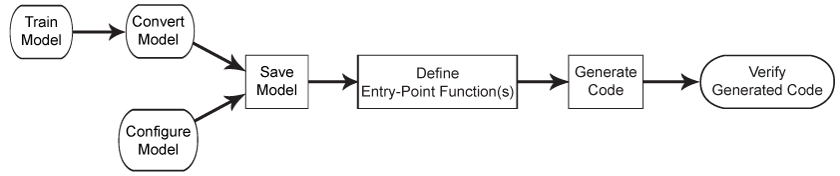

The flow chart suggests two distinct but merging workflows.

- The workflow beginning with **Train Model > Convert Model** requires data, in which case you can optionally perform feature selection or optimize the model by performing cross-validation before generating code for incremental learning. 

- The workflow beginning with **Configure Model** does not require data. Instead, you must manually configure an incremental learning model object.

For details on the differences between the workflows, and for help deciding which one to use, see [docid:stats_ug#mw_c4753575-71f7-4623-99c9-c480157b9f23](docid:stats_ug#mw_c4753575-71f7-4623-99c9-c480157b9f23).

Regardless of the workflow you choose, the resulting incremental learning model must have all the following qualities:

- The `NumPredictors` property reflect the number of predictors in the predictor data during incremental learning.

- For classification, the `ClassNames` property must contain all class names expected during incremental learning.

If you choose the **Train Model > Convert Model** workflow and you fit the model to data containing all known classes, the model is configured for code generation. 

After you prepare an incremental learning model, save the model object by using `saveLearnerForCoder`. Then, define an entry-point function that loads the saved model by using `loadLearnerForCoder`, and that performs incremental learning by calling the object functions. Alternatively, you can define multiple entry-point functions that perform the stages of incremental learning separately (this example uses this workflow). However, this workflow requires special treatment when an updated model object is an input to another entry-point function. For example, you write the following three entry-point functions: 

- A function that accepts the current model and a batch of data, calls [`updateMetrics`](docid:stats_ug#mw_c5db68b3-16a1-4b8b-90b9-7f3c76289dce), and returns a model with updated performance metrics.

- A function that accepts the updated model and the batch of data, calls [`fit`](docid:stats_ug#mw_665feb66-5ad1-4a02-8d42-32a1a738997c), and returns a model with updated coefficients. 

- A function that accepts the further updated model and the batch of predictor data, calls [`predict`](docid:stats_ug#mw_1d13a443-0b4a-44bb-a4df-c34b8a9ce1d5), and returns predicted labels.

Finally, generate code for the entry-point functions by using `codegen`, and verify the generated code. 

## Load and Preprocess Data

Load the human activity data set. Randomly shuffle the data.

load humanactivity
rng(1); % For reproducibility
n = numel(actid);
p = size(feat,2);
idx = randsample(n,n);
X = feat(idx,:);
actid = actid(idx);

For details on the data set, enter `Description` at the command line.

Responses can be one of five classes: Sitting, Standing, Walking, Running, or Dancing. Dichotomize the response by identifying whether the subject is idle (`actid` <= 2). Store the unique class names. Create categorical arrays.

classnames = categorical(["Idle" "NotIdle"]);
Y = repmat(classnames(1),n,1);
Y(actid > 2) = classnames(2);

## Configure Incremental Learning Model

To generate code for incremental classification, you must appropriately configure a binary classification linear model for incremental learning `incrementalClassificationLinear`. 

Create a binary classification (SVM) model for incremental learning.  Fully configure the model for code generation by specify all expected class names and the number of predictor variables. Also, specify tracking the misclassification rate and hinge loss. For reproducibility, this example turns off observation shuffling for the scale-invariant solver.

metrics = ["classiferror" "hinge"];
IncrementalMdl = incrementalClassificationLinear('ClassNames',classnames,'NumPredictors',p,...
    'Shuffle',false,'Metrics',metrics)

IncrementalMdl =   incrementalClassificationLinear

            IsWarm: 0
           Metrics: [2×2 table]
        ClassNames: [Idle    NotIdle]
    ScoreTransform: 'none'
              Beta: [60×1 double]
              Bias: 0
           Learner: 'svm'


  Properties, Methods


`Mdl` is an `incremenalClassificationLinear` model object configured for code generation. `Mdl` is *cold* (`Mdl.IsWarm` is `0`) because it has not processed data—the coefficients are `0`.

Alternatively, because the data is available, you can fit an SVM model to the data by using either `fitcsvm` or `fitclinear`, and then convert the resulting model to an incremental learning model by passing the model to `incrementalLearner`. The resulting model is *warm* because it has processed data—its coefficients are likely non-zero.

## Save Model Using `saveLearnerForCoder`

Save the incremental learning model to the file `InitialMdl.mat` by using [`saveLearnerForCoder`](docid:stats_ug.bvclu99). 

saveLearnerForCoder(IncrementalMdl,'InitialMdl');

`saveLearnerForCoder` saves the incremental learning model to the MATLAB binary file `SVMClassIncrLearner.mat` as structure arrays in the current folder.

## Define Entry-Point Functions

An *entry-point* function, also known as the *top-level* or *primary* function, is a function you define for code generation. Because you cannot call any function at the top level using `codegen`, you must define an entry-point function that calls code-generation-enabled functions, and generate C/C++ code for the entry-point function by using `codegen`. All functions within the entry-point function must support code generation.

Define four separate entry-point functions in your current folder that perform the following actions:

- `myInitialModelIncrLearn.m` — Load the saved model by using [`loadLearnerForCoder`](docid:stats_ug.bvcl05n-1), and return a model of the same form for code generation. This entry-point function facilitates the use of a model, returned by an entry-point function, as an input to another entry-point function.

- `myUpdateMetricsIncrLearn.m` — Measure the performance of the current model on an incoming batch of data, and store the performance metrics in the model. The function accepts the current model, and predictor and response data, and returns an updated model.

- `myFitIncrLearn.m` — Fit the current model to the incoming batch of data, and store the updated coefficients in the model. The function accepts the current model, and predictor and response data, and returns an updated model. 

- `myPredictIncrLearn.m` — Predicted labels for the incoming batch of data using the current model. The function accepts the current model and predictor data, and returns labels and class scores.

For more details on generating code for multiple entry-point functions, see [docid:coder_ug#bsd8i4b-1](docid:coder_ug#bsd8i4b-1).

Add the `%#codegen` compiler directive (or pragma) to the entry-point function after the function signature to indicate that you intend to generate code for the MATLAB algorithm. Adding this directive instructs the MATLAB Code Analyzer to help you diagnose and fix violations that would result in errors during code generation. See [Check Code with the Code Analyzer](docid:coder_ug.btln3cg).

Alternatively, you can access the functions in `mlr/examples/stats/main`, where `mlr` is the value of `matlabroot`.

Display the body of each function.

type myInitialModelIncrLearn.m

function incrementalModel = myInitialModelIncrLearn() %#codegen
% MYINITIALMODELINCRLEARN Load and return configured linear model for
% binary classification InitialMdl
    incrementalModel = loadLearnerForCoder('InitialMdl');
end


type myUpdateMetricsIncrLearn.m

function incrementalModel = myUpdateMetricsIncrLearn(incrementalModel,X,Y) %#codegen
% MYUPDATEMETRICSINCRLEARN Measure model performance metrics on new data
      incrementalModel = updateMetrics(incrementalModel,X,Y); 
end


type myFitIncrLearn.m

Error using type
File 'myFitIncrLearn.m' not found.

type myPredictIncrLearn.m

## Generate Code

**Set Up Compiler**

To generate C/C++ code, you must have access to a C/C++ compiler that is configured properly. MATLAB Coder locates and uses a supported, installed compiler. You can use `mex` `-setup` to view and change the default compiler. For more details, see [Change Default Compiler](docid:matlab_external.btw3qmj).

**Build Type**

MATLAB Coder can generate code for the following build types: 

- MEX (MATLAB Executable) function

- Standalone C/C++ code

- Standalone C/C++ code compiled to a static library

- Standalone C/C++ code compiled to a dynamically linked library

- Standalone C/C++ code compiled to an executable

You can specify the build type using the `-config` option of [`codegen`](docid:coder_ref.br46oyi-1). For more details on setting code generation options, see the `-config` option of [`codegen`](docid:coder_ref.br46oyi-1) and [Configure Build Settings](docid:coder_ug.bsw7_wl).

By default, `codegen` generates a MEX function. A MEX function is a C/C++ program that is executable from MATLAB. You can use a MEX function to accelerate MATLAB algorithms and to test the generated code for functionality and run-time issues. For details, see [MATLAB Algorithm Acceleration](docid:coder_doccenter#bs2r9v8-1) and [Why Test MEX Functions in MATLAB?](docid:coder_ug#bu7q816-1).

**Generate Code Using **`codegen`

Because C and C++ are statically typed languages, you must specify the properties of all variables in the entry-point function at compile time. Specify the following:

- The data types of the data inputs of the entry-point functions by using [`coder.typeof`](docid:coder_ref.bsu_35x). Also, because the number of observations can vary from batch to batch, specify that the number of observations (first dimension) has variable size. For details, see [Specify Variable Sized Arguments for Code Generation](docid:stats_ug.bvnu22q) and [Specify Properties of Entry-Point Function Inputs](docid:coder_ug.bq9_nbz).

- Because several entry-point functions accept an incremental model object as a input, and operate on it, create a representation of the model object for code generation by using [`coder.OutputType`](docid:coder_ref#mw_186147ed-8160-4651-9402-66b666c36a83). For more details, see [docid:coder_ug#mw_3673faa4-a8d2-472f-a7a6-28989f410538](docid:coder_ug#mw_3673faa4-a8d2-472f-a7a6-28989f410538).

predictorData = coder.typeof(X,[],[true false]); 
responseData = coder.typeof(Y,[],true);
IncrMdlOutputType = coder.OutputType('myInitialModelIncrLearn');

Generate code for the entry-point functions using [`codegen`](docid:coder_ref.br46oyi-1).  For each entry-point function argument, use the `-args` flags to specify the coder representations of the variables. Specify the output MEX function name `myIncrLearn_mex`. 

 codegen -o myIncrLearn_mex ...
 myInitialModelIncrLearn ... 
 myUpdateMetricsIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myFitIncrLearn -args {IncrMdlOutputType,predictorData,responseData} ...
 myPredictIncrLearn –args {IncrMdlOutputType,predictorData} -report

For help debugging code generation issues, view the generated C/C++ code by clicking `View report` (see [Code Generation Reports](docid:coder_ug.brbmkp4-1)).

## Verify Generated Code

Test the MEX function to verify that the generated code provides the same functionality as the original MATLAB code. To perform this test, run the MEX function using the same inputs that you used to run the original MATLAB code, and then compare the results. Running the MEX function in MATLAB before generating standalone code also enables you to detect and fix run-time errors that are much harder to diagnose in the generated standalone code. For more details, see [Why Test MEX Functions in MATLAB?](docid:coder_ug#bu7q816-1).

Perform incremental learning by using the generated MEX functions and directly by using the object functions. Specify a batch 

% Preallocation
numObsPerChunk = 50;
nchunk = floor(n/numObsPerChunk);
ce = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
hinge = ce;
ceCG = ce;
hingeCG = ce;
IncrementalMdlCG = myIncrLearn_mex('myInitialModelIncrLearn');
scores = zeros(n,2);
scoresCG = zeros(n,2);

% Incremental fitting
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend;

    IncrementalMdl = updateMetrics(IncrementalMdl,X(idx,:),Y(idx));
    ce{j,:} = IncrementalMdl.Metrics{"ClassificationError",:};
    hinge{j,:} = IncrementalMdl.Metrics{"HingeLoss",:};
    IncrementalMdlCG = myIncrLearn_mex('myUpdateMetricsIncrLearn',IncrementalMdlCG,...
        X(idx,:),Y(idx));
    ceCG{j,:} = IncrementalMdlCG.Metrics{"ClassificationError",:};
    hingeCG{j,:} = IncrementalMdlCG.Metrics{"HingeLoss",:};

    IncrementalMdl = fit(IncrementalMdl,X(idx,:),Y(idx));
    IncrementalMdlCG = myIncrLearn_mex('myFitIncrLearn',IncrementalMdlCG,X(idx,:),Y(idx));
    
    [~,scores(idx,:)] = predict(IncrementalMdl,X(idx,:));
    [~,scoresCG(idx,:)] = myIncrLearn_mex('myPredictIncrLearn',IncrementalMdlCG,X(idx,:));
end

Compare the cumulative metrics and scores for classifying `Idle` returned by the object functions and MEX functions.

idx = all(~isnan(ce.Variables),2);
areCEsEqual = norm(ce.Cumulative(idx) - ceCG.Cumulative(idx))
idx = all(~isnan(hinge.Variables),2);
areHingeLossesEqual = norm(hinge.Cumulative(idx) - hingeCG.Cumulative(idx))
areScoresEqual = norm(scores(:,1) - scoresCG(:,1))

The differences between the returned quantities are negligible.

*Copyright 2021 The MathWorks, Inc.*